T = 0.03;
%delovna točka
U00 = 5.1
Y00 = 5.3464
t = 0:T:60;
simin_val = 5.1:0.25:6.1;
simin = simin_val'
% mrtva cona se konča pri 4.6
% gremo do cca 7
% najprej probat na 0.25V natančno

% vhodni signal
toWorkspace = 5;

Y_all = [Y_46.Data,Y_485.Data,Y_51.Data,Y_535.Data,Y_56.Data,Y_585.Data,Y_61.Data,Y_635.Data,Y_66.Data,Y_685.Data];

Y_end = mean(Y_all(end-30:end,:),1)

plot(simin_val,Y_end)



plot(Y_all(3))



%plot(Y_56.Data)
U_PRBS = prbs(10) + 5.1
U_PRBS_T = prbs(10) + 5.1
U = ones(7500,1)*5.1
U_T = ones(length(t)-length(U_PRBS_T),1)*5.1

plot(U)

figure
%plot(U_PRBS)
plot(Y_all)


U_prbs = [U;U_PRBS]
U_prbs_T = [U_T;U_PRBS_T]
U_prbs_11 = [U;prbs(11)+5.1]
U_prbs_12 = [U;prbs(12)+5.1]
%plot(U_prbs)

PRBS_true = [t',U_prbs_T]


% plot(out.simout)
% exp_1 = [PRBS_true,out.simout.Data]

t = final(70:end,1);
u = final(70:end,2)-5.6;
y = final(70:end,3)-4.9;


figure
plot(t,-u)
figure
stairs(t,y)

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F) %frequency vector

## FFT

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:end/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

plot(v,abs(FT_input(1:end/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

G_jw = FT_output ./ FT_input;
faza = unwrap(angle(G_jw));

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:end/2))))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")
subplot(2,1,2), semilogx(v,180/pi*(faza(1:end/2)))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")


n = 2;
d = 2;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end


y_short = y((n+d+1):end);
Th = psi \ y_short;
T = T*2*pi;
G = tf([Th(3) Th(4)],[1 Th(1) Th(2)], T); 
G.inputdelay = d;
%G = tf([Th(4) Th(5) Th(6)],[1 Th(1) Th(2) Th(3)], T);


N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector

figure
bode(G,v);
[MAG, PH]=bode(G, v);
MAG = MAG(:);
PH = PH(:);
FT_input = fft(u);
FT_output = fft(y);

% G_jw = FT_output ./ FT_input;
% faza = unwrap(angle(G_jw));
figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:end/2))))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(faza(1:end/2)))
hold on
subplot(2,1,2), semilogx(v,PH)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")


% prbs_9 = [prbs(8),prbs(8),prbs(8),prbs(8)];
% prbs_9t = prbs_9';
% prbs_10 = prbs_9t(:);
prbs_10 = prbs(8);
N_prbs = length(prbs_10);
random_array = rand(N_prbs, 1) - 0.5;
nice_array = random_array .* prbs_10;


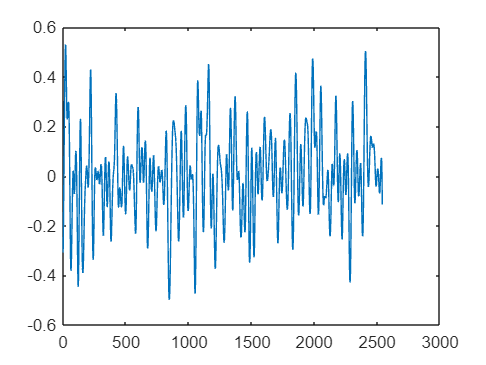

% Assume prbs_10 and nice_array are defined as shown in your message

% Calculate the FFT of the nice_array
fft_nice_array = fft(nice_array);

% Determine the cutoff frequency (as a fraction of the Nyquist frequency)
cutoff_fraction = 0.7; % For example, 10% of the Nyquist frequency
cutoff_idx = ceil(cutoff_fraction * (N_prbs / 2));

% Create a low-pass filter mask
filter_mask = zeros(N_prbs, 1);
filter_mask(1:cutoff_idx+1) = 1; % Pass low frequencies
filter_mask(end-cutoff_idx+1:end) = 1; % Pass the symmetric high frequencies

% Apply the filter mask to the FFT of the nice_array
filtered_fft_nice_array = fft_nice_array .* filter_mask;

% Perform the inverse FFT to get the smoothed array
smoothed_nice_array = ifft(filtered_fft_nice_array);

% In case the imaginary part is non-zero due to numerical errors, take only the real part
smoothed_nice_array = real(smoothed_nice_array);

% Upsample the smoothed array by a factor of 4
upsampled_rate = 10;
upsampled_smoothed_nice_array = interp1(1:N_prbs, smoothed_nice_array, 1:1/upsampled_rate:N_prbs, 'spline');
figure
plot(upsampled_smoothed_nice_array)

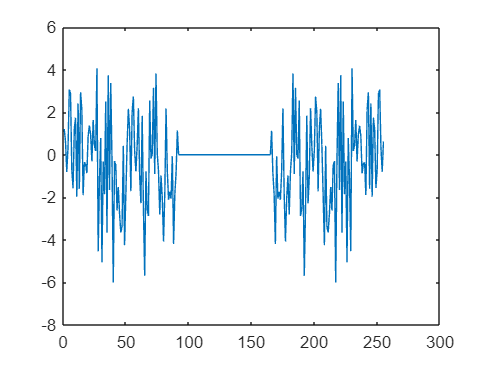

figure
plot(real(filtered_fft_nice_array))


L = length(upsampled_smoothed_nice_array);
Ts = 90;
T = Ts/(L-1)

T = 0.0354

t = 0:T:Ts;
PRBS_true = [t',upsampled_smoothed_nice_array'+5.6]

PRBS_true =          0    5.2922
    0.0354    5.3315
    0.0709    5.3758
    0.1063    5.4245
    0.1417    5.4767
    0.1772    5.5316
    0.2126    5.5884
    0.2480    5.6462
    0.2835    5.7043
    0.3189    5.7618


## tier 1.5

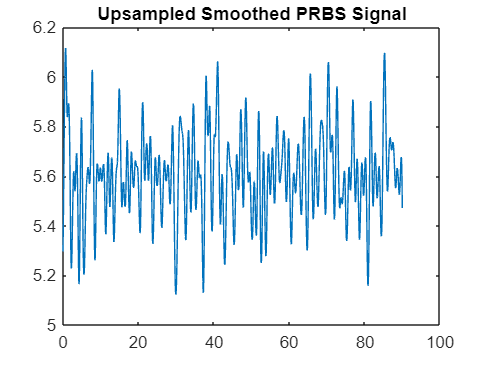

% Calculate the FFT of the nice_array
fft_nice_array = fft(nice_array);

% Determine the cutoff frequency (as a fraction of the Nyquist frequency)
cutoff_fraction = 0.7;
cutoff_idx = ceil(cutoff_fraction * (N_prbs / 2));

% Create a low-pass filter mask for only the first half
filter_mask = zeros(N_prbs, 1);
filter_mask(1:cutoff_idx+1) = 1; % Pass low frequencies in the first half

% Mirror the first half into the second half for real signal requirement
filter_mask(end-cutoff_idx:end) = filter_mask(2:cutoff_idx+2);

% Apply the filter mask to the FFT of the nice_array
filtered_fft_nice_array = fft_nice_array .* filter_mask;

% Perform the inverse FFT to get the smoothed array
smoothed_nice_array = ifft(filtered_fft_nice_array);

% Convert to real to remove any tiny imaginary parts due to computation
smoothed_nice_array = real(smoothed_nice_array);

% Upsample the smoothed array by a factor of 10
upsampled_smoothed_nice_array = interp1(1:N_prbs, smoothed_nice_array, linspace(1, N_prbs, 10*N_prbs), 'spline');

% Create time vector and adjust the base level of the upsampled signal
Ts = 90;  % Total time span
L = length(upsampled_smoothed_nice_array);
T = Ts / (L - 1);  % Time step
t = 0:T:Ts;
PRBS_true = [t', upsampled_smoothed_nice_array' + 5.6];

% Plotting the resulting upsampled smoothed array
figure;
plot(t, PRBS_true(:,2));
title('Upsampled Smoothed PRBS Signal');

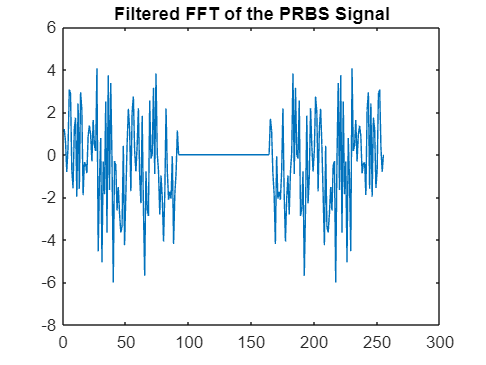


% Optionally, plot the filtered FFT to verify the frequency domain manipulation
figure;
plot(real(filtered_fft_nice_array));
title('Filtered FFT of the PRBS Signal');

## tier 2

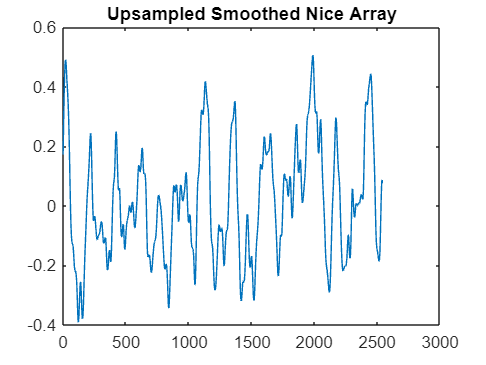

% Assume prbs_10 and nice_array are defined as shown in your message

% Calculate the FFT of the nice_array
fft_nice_array = fft(nice_array);

% Determine the total number of points
N_prbs = length(prbs_10);

% Calculate the index for 20% of the frequencies
cutoff_20_idx = ceil(0.2 * (N_prbs / 2));

% Calculate the index for 80% of the frequencies
cutoff_80_idx = ceil(0.8 * (N_prbs / 2));

% Create a filter mask
filter_mask = zeros(N_prbs, 1); % Start with all zeros to cut off high frequencies

% Pass the lowest 20% of frequencies
filter_mask(1:cutoff_20_idx+1) = 1; % Include the zero-frequency bin
filter_mask(end-cutoff_20_idx+1:end) = 1; % Symmetric for the negative frequencies

% Attenuate the next portion up to 80% of frequencies by 80%
filter_mask(cutoff_20_idx+1:cutoff_80_idx) = 0.1; % Lower the amplitude by 80%
filter_mask(end-cutoff_80_idx+1:end-cutoff_20_idx) = 0.1; % Apply symmetrically

% Apply the filter mask to the FFT of the nice_array
filtered_fft_nice_array = fft_nice_array .* filter_mask;

% Perform the inverse FFT to get the filtered array
smoothed_nice_array = ifft(filtered_fft_nice_array);

% Normalize the data to be between -0.5 and 0.5
max_val = max(abs(smoothed_nice_array));
smoothed_nice_array = (smoothed_nice_array / max_val) * 0.5;

% In case the imaginary part is non-zero due to numerical errors, take only the real part
smoothed_nice_array = real(smoothed_nice_array);

% Upsample the smoothed array by a factor of 10
upsampled_rate = 10;
upsampled_smoothed_nice_array = interp1(1:N_prbs, smoothed_nice_array, 1:1/upsampled_rate:N_prbs, 'spline');

% Plotting the results
figure
plot(upsampled_smoothed_nice_array)
title('Upsampled Smoothed Nice Array')

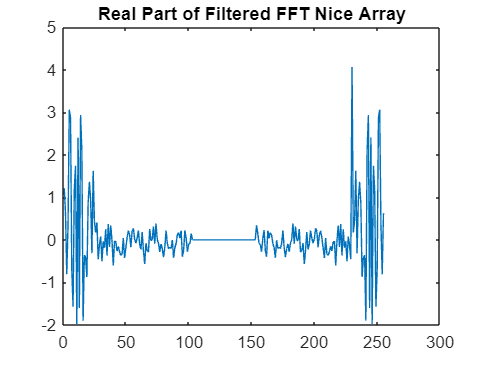


figure
plot(real(filtered_fft_nice_array))
title('Real Part of Filtered FFT Nice Array')


% Calculate the time vector for plotting
L = length(upsampled_smoothed_nice_array);
Ts = 90; % Total time span
T = Ts / (L - 1); % Time step
t = 0:T:Ts;

% Create a table with time and data
PRBS_true = [t', upsampled_smoothed_nice_array'];

## i tried

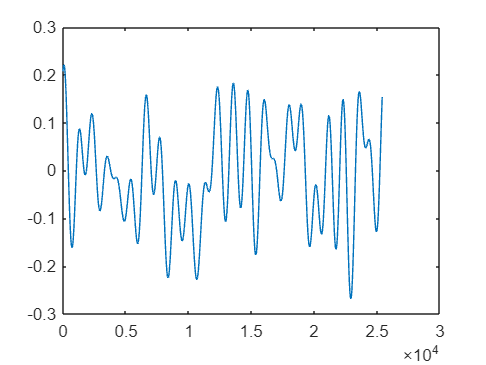

Ts = 60; %s
T = 0.001; %s
prbs_6 = prbs(8);
N_prbs = length(prbs_6);
random_array = rand(N_prbs, 1) - 0.5;
nice_array = random_array .* prbs_6;

% Assume a sampling frequency Fs
Fs = 1/T; % Replace 1000 with your actual sampling rate in Hz

% Calculate the FFT of the nice_array
fft_nice_array = fft(nice_array);

% Frequency resolution
frequency_resolution = Fs / N_prbs;

% Determine indices for 1 Hz and 100 Hz
index_1Hz = ceil(1 / frequency_resolution);
index_100Hz = floor(100 / frequency_resolution);

% Create a band-pass filter mask
filter_mask = zeros(N_prbs, 1);
filter_mask(index_1Hz:index_100Hz) = 1; % Pass frequencies between 1 Hz and 100 Hz
filter_mask(N_prbs-index_100Hz+1:N_prbs-index_1Hz+1) = 1; % Symmetrically pass the frequencies in the upper half

% Apply the filter mask to the FFT of the nice_array
filtered_fft_nice_array = fft_nice_array .* filter_mask;

% Perform the inverse FFT to get the smoothed array
smoothed_nice_array = ifft(filtered_fft_nice_array);

% In case the imaginary part is non-zero due to numerical errors, take only the real part
smoothed_nice_array = real(smoothed_nice_array);

% Upsample the smoothed array by a factor of 4 (if still needed)
upsampled_rate = 100; % Example upsample rate
upsampled_smoothed_nice_array = interp1(1:N_prbs, smoothed_nice_array, 1:1/upsampled_rate:N_prbs, 'spline');
plot(upsampled_smoothed_nice_array)

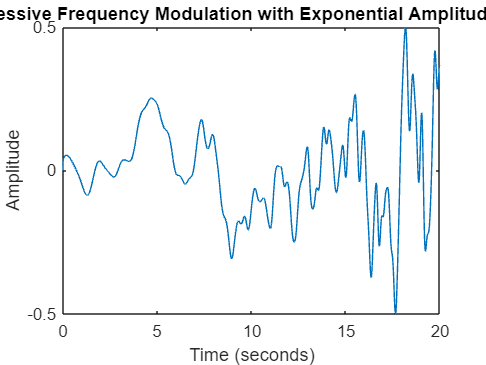

% Define parameters
Fs = 100;                 % Sampling frequency in Hz
T = 1/Fs;                 % Sampling period in s
L = 2000;                 % Total number of samples
t = (0:L-1)*T;            % Time vector

% Frequency range
f_min = 0.05;             % Minimum frequency in Hz
f_max = 5;                % Maximum frequency in Hz

% Generate frequencies spaced by 0.05 Hz from f_min to f_max
frequencies = f_min:0.05:f_max;  % This creates a vector of frequencies from 0.05 Hz to 5 Hz
num_frequencies = length(frequencies);

% Initialize the signal
signal = zeros(1, L);

% Generate the signal by summing sinusoids at each frequency
for i = 1:num_frequencies
    % Create a ramp-up modulation for each frequency
    % The ramp is more gradual for higher frequencies
    modulation = linspace(0, 1, L).^((i/num_frequencies)*5);  % The exponent increases with frequency index

    % Apply exponential decay to the amplitude as frequency increases
    amplitude_decay_factor = exp(-((i-1) / (num_frequencies-1)) * log(20));  % Log(20) ensures the amplitude is reduced by a factor of 20 from the lowest to the highest frequency

    amplitude = amplitude_decay_factor;  % Apply decay factor to amplitude

    phase = rand(1) * 2 * pi; % Random phase for each frequency component
    signal = signal + amplitude * modulation .* sin(2 * pi * frequencies(i) * t + phase);
end

% Normalize the signal to range from 0.5 to -0.5
signal = (signal - min(signal)) / (max(signal) - min(signal)); % Normalize to [0, 1]
signal = 1 - signal;  % Invert to go from 1 to 0
signal = 0.5 - signal;  % Scale and shift to [0.5, -0.5]

% Plot the signal
figure;
plot(t, signal);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Progressive Frequency Modulation with Exponential Amplitude Decay');

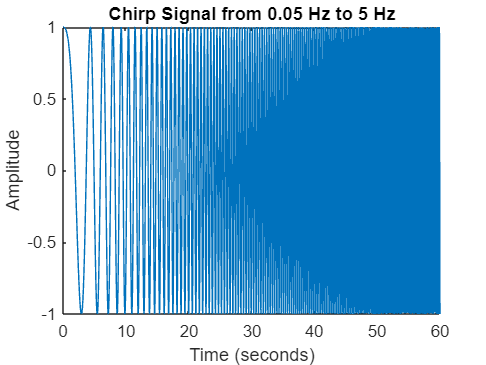

% Define the signal parameters
Fs = 100;               % Sampling frequency (1/sampling rate)
T = 60;                 % Total time in seconds
t = linspace(0, T, T*Fs);  % Time vector from 0 to T seconds with Fs sampling frequency

% Frequency range
f0 = 0.05;              % Start frequency in Hz
f1 = 5;                 % End frequency in Hz

% Generate the chirp signal
signal = chirp(t, f0, T, f1);

% Plot the signal
figure;
plot(t, signal);
title('Chirp Signal from 0.05 Hz to 5 Hz');
xlabel('Time (seconds)');
ylabel('Amplitude');


% Optionally, you can listen to the signal if you want to check its characteristics
sound(signal, Fs);

Error using sound
Device Error: Invalid sample rate